% Objective: Display raw and averaged spiking data
% What you need: Aligned spiketimes per trial
% Example data: Cortical multi-unit responses to repeated presentation of pure tone

## Felix Schneider

## Auditory Cognition Group: [https://www.auditorycognition.org/](https://www.auditorycognition.org/)

## Biosciences Institute, Newcastle University Medical School

## 02/2020

load('sptimes.mat')

## Raster plot

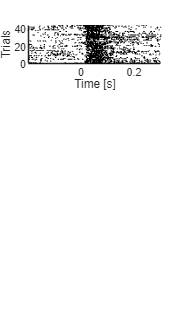

figure('Units','normalized','Position',[0 0 .3 1])
ax = subplot(4,1,1); hold on

% For all trials...
for iTrial = 1:length(sptimes)
    
    spks            = sptimes{iTrial}';         % Get all spikes of respective trial
    xspikes         = repmat(spks,3,1);         % Replicate array
    yspikes      	= nan(size(xspikes));       % NaN array
    
    if ~isempty(yspikes)
        yspikes(1,:) = iTrial-1;                % Y-offset for raster plot
        yspikes(2,:) = iTrial;
    end
    
    plot(xspikes, yspikes, 'Color', 'k')
end

ax.XLim             = [-.2 .3];
ax.YLim             = [0 length(sptimes)];
ax.XTick            = [0 .2];

ax.XLabel.String  	= 'Time [s]';
ax.YLabel.String  	= 'Trials';


% to create csv of the .mat file - writecell(sptimes, 'data.csv') in
% command window

## Peristimulus time histogram (PSTH)

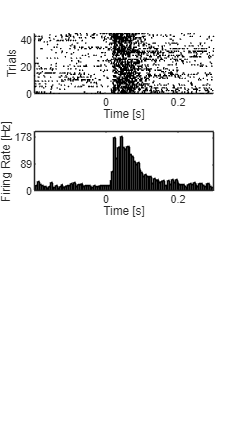

all = [];
for iTrial = 1:length(sptimes)
    all             = [all; sptimes{iTrial}];               % Concatenate spikes of all trials
end

ax                  = subplot(4,1,2);
nbins               = 100;
h                   = histogram(all,nbins);
h.FaceColor         = 'k';

mVal                = max(h.Values)+round(max(h.Values)*.1);
ax.XLim             = [-.2 .3];
ax.YLim             = [0 mVal];
ax.XTick            = [0 .2];
ax.XLabel.String  	= 'Time [s]';
ax.YLabel.String  	= 'Spikes/Bin';

slength             = 500;                                  % Length of signal trace [ms]
bdur                = slength/nbins;                        % Bin duration in [ms]
nobins              = 1000/bdur;                            % No of bins/sec
for iLab = 1:length(ax.YTickLabel)
    lab             = str2num(ax.YTickLabel{iLab});
    conv            = (lab / length(sptimes)) * nobins; 	% Convert to [Hz]: avg spike count * bins/sec
    newlabel{iLab}  = num2str(round(conv));                 % Change YLabel
end
ax.YTickLabel       = newlabel;
ax.YLabel.String  	= 'Firing Rate [Hz]';

## Spike density function

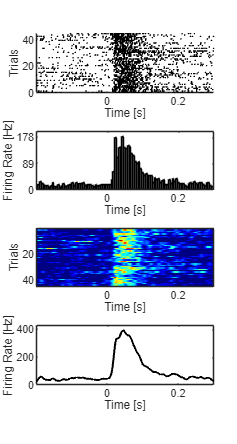

tstep     	= .001;                     % Resolution for SDF [s]
sigma   	= .005;                     % Width of gaussian/window [s]
time     	= tstep-.2:tstep:.3;        % Time vector

for iTrial = 1:length(sptimes)
    spks    = [];
    gauss   = [];
    spks   	= sptimes{iTrial}';          % Get all spikes of respective trial
    
    if isempty(spks)
        out	= zeros(1,length(time));    % Add zero vector if no spikes
    else
        
        % For every spike
        for iSpk = 1:length(spks)
            
            % Center gaussian at spike time
            mu              = spks(iSpk);
            
            % Calculate gaussian
            p1              = -.5 * ((time - mu)/sigma) .^ 2;
            p2              = (sigma * sqrt(2*pi));
            gauss(iSpk,:)   = exp(p1) ./ p2;
            
        end
        
        % Sum over all distributions to get spike density function
        sdf(iTrial,:)       = sum(gauss,1);
    end
end

% Single trial display
ax                  = subplot(4,1,3);
imagesc(sdf)
ax.XLabel.String  	= 'Time [s]';
ax.YLabel.String  	= 'Trials';
ax.XLim             = [1 500];
ax.XTick            = [200 400];
ax.XTickLabel       = {'0', '0.2'};
colormap jet

% Average response
ax = subplot(4,1,4);
plot(mean(sdf), 'Color', 'k', 'LineWidth', 1.5)
mVal = max(mean(sdf)) + round(max(mean(sdf))*.1);

ax.XLim             = [0 500];
ax.YLim             = [0 mVal];
ax.XTick            = [200 400];
ax.XTickLabel       = {'0', '0.2'};
ax.XLabel.String  	= 'Time [s]';
ax.YLabel.String  	= 'Firing Rate [Hz]';